%Linear regression with MULTIPLE VARIABLES
%HOUSE Problem: where PRICE is determined by the SIZE & NoOfBedrooms
data=load("ex1data2.txt");
X=data(:,1:2)   %SIZE and BEDROOMS

X =         2104           3
        1600           3
        2400           3
        1416           2
        3000           4
        1985           4
        1534           3
        1427           3
        1380           3
        1494           3


y=data(:,3)     %PRICE, to be predicted

y =       399900
      329900
      369000
      232000
      539900
      299900
      314900
      198999
      212000
      242500


%FEATURE NORMALIZATION
[X_Normal,Mu, Sig]=featureNormalize(X);

mu = 	1.0e+03 *

    2.0007    0.0032


sigma =   794.7024    0.7610


X_norm =     0.1300   -0.2237
   -0.5042   -0.2237
    0.5025   -0.2237
   -0.7357   -1.5378
    1.2575    1.0904
   -0.0197    1.0904
   -0.5872   -0.2237
   -0.7219   -0.2237
   -0.7810   -0.2237
   -0.6376   -0.2237


%Adding BIAS term to X
SizeX=size(X,1);
X_Normal=[ones(SizeX,1) X_Normal]

X_Normal =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


%GRADIENT DESCENT to set the right THETA
theta=zeros(size(X_Normal,2),1) %initializing THETA values

theta =      0
     0
     0


Iterations=130   % No of iterations

Iterations = 130

AlphaVal=0.03           %Learning Rate

AlphaVal = 0.0300


    %COST FUNCTION is calculated at each of iteration loop [CALCULATES THE OPTIMIZED THETA]
    [theta,J_His]=gradientDescentMulti(X_Normal,y,theta,AlphaVal,Iterations)

theta = 	1.0e+05 *

    3.3392
    0.9970
    0.0405


J_His = 	1.0e+10 *

    6.1760
    5.8165
    5.4791
    5.1624
    4.8653
    4.5863
    4.3244
    4.0785
    3.8477
    3.6309


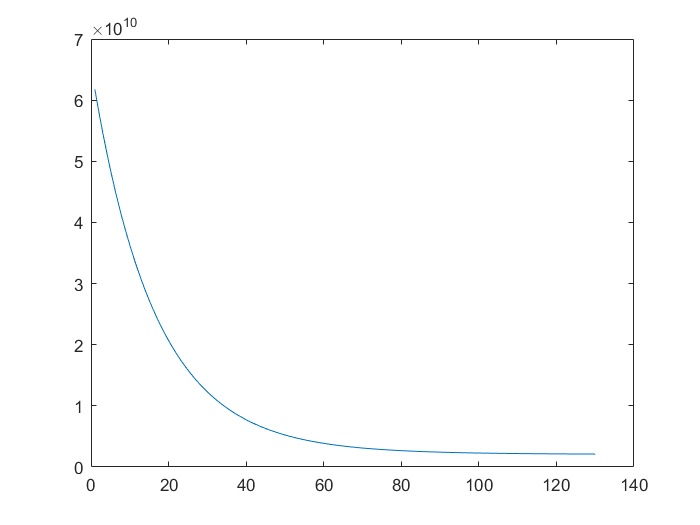

      
    %DISPLAY GRADIENT DESCENT vs Iterations
    plot(1:Iterations,J_His)

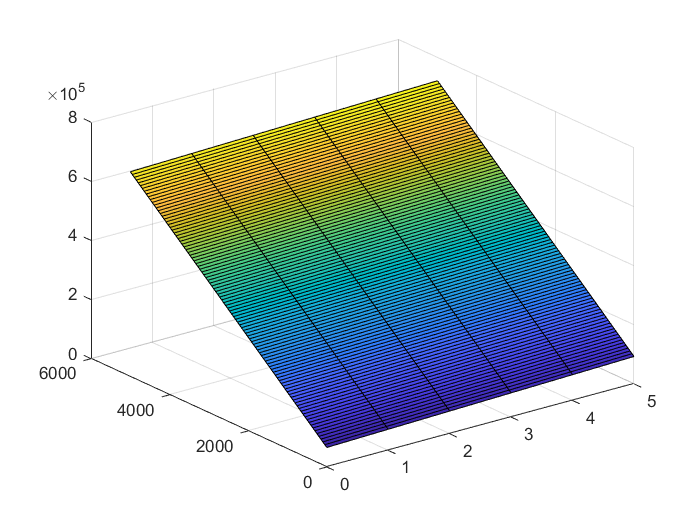

    
    %Display BEST FIT SURFACE vs FEATURES (Area, Bedrooms)
    divs=50;    %No. of divisions
    X1=linspace(0,5000,100)';   %Size
    X2=linspace(0,5,6)';        %Bedrooms
    X1_Norm=(X1-Mu(:,1))./Sig(:,1);
    X2_Norm=(X2-Mu(:,2))./Sig(:,2);
    
    Price=zeros(size(X1,1),size(X2,1));
    
    for i=1:size(Price,1)   %Size
        for j=1:size(Price,2)   %Bedrooms
            %fprintf("Price of a house with %.0f size and %.0f bedrooms: %.0f",NewArea,NewSize,NewPrice);
            Price(i,j)=[1,X1_Norm(i),X2_Norm(j)]*theta;            
        end
    end
    
    surf(X2,X1,Price)

%Display the BEST FIT SURFACE vs the THETA1 & THETA2
    T0=theta(1,:)

T0 = 3.3392e+05

    T1=linspace(1,20000,5000)';
    T2=linspace(1,20000,5000)';
    
    J_values=zeros(size(T1,1),size(T2,1));    %Creating 2D-MESH of the input data
    for i=1:size(T1,1)  %Theta1
        for j=1:size(T2,1)  %Theta2
            T123=[T0,T1(i,:),T2(j,:)];
            J_values(i,j)=computeCostMulti(X_Normal,y,T123');    %Calcualting the Cost function on the existing dataset
        end
    end

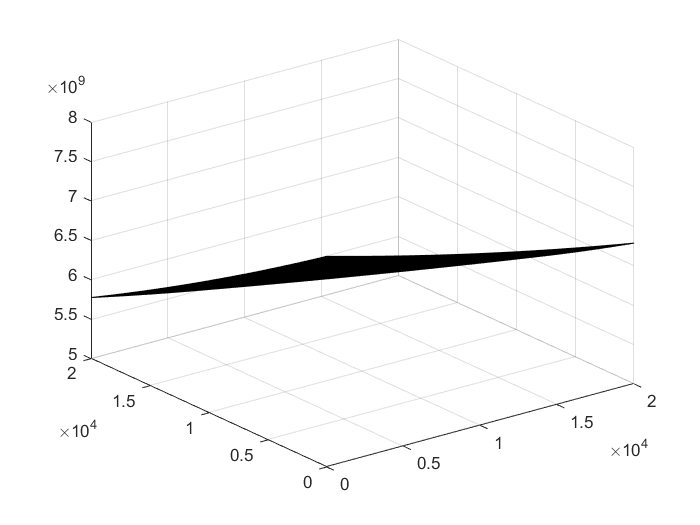

    %Show the 3D-Surface
    surf(T1, T2, J_values)

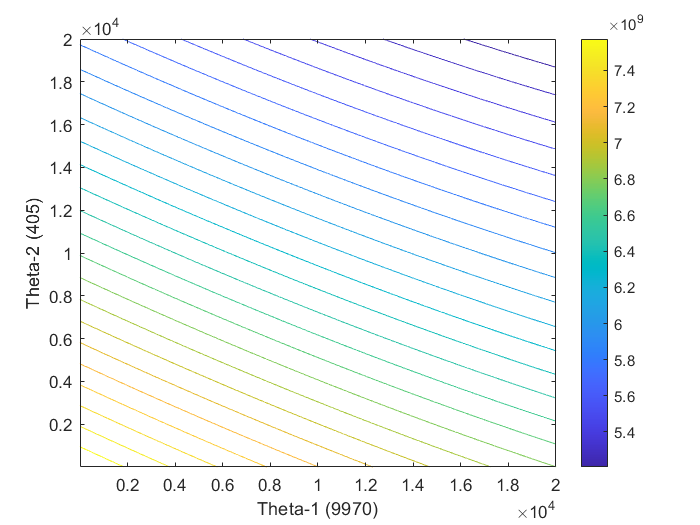

   
    
    %Show in Contour
    contour(T1,T2,J_values,25)
    xlabel('Theta-1 (9970)')
    ylabel('Theta-2 (405)')    
    xlim([1 20000])
    ylim([1 20000])
    colorbar

%PREDICTION
NewArea=5000;
NewSize=5;
NewAreaSize=([NewArea,NewSize]-Mu)./Sig;
NewPrice=[ones(1), NewAreaSize(:,1), NewAreaSize(:,2)]*theta;
fprintf("Price of a house with %.0f size and %.0f bedrooms: %.0f",NewArea,NewSize,NewPrice);